%function plotNbHeatmap(Tonal, Fz, SPL, par, proc, timeCPA, tog, timeVector)

### Plot narrowband lobing heatmap for tonals

runLoad = 1; %switch for whether to load or not
nw = 90; %number of discrete angle steps (w)
nSL = 50; %number of discrete SL steps
iTonal = 3;  

%debug mode
if runLoad == 1
    addpath 'C:\Users\510PAS\PhD\Code\MATLAB\perfectPolarPlot'
    tog.VOI = 'Amundsen-AAA2-29Aug19';
    par = setPars;
    load(fullfile(par.procPath,tog.VOI));
    clear S Sz array1 array2 BB CPA
end

can add this back in later

% if ~mod((exampSpec.dir(1) - exampSpec.dir(end)), 360)
%    exampSpec.dir(end+1) = exampSpec.dir(1) + 360;
%    exampSpec.spec(:,end+1) = exampSpec.spec(:,1);
% end

In this case the freq ---> SL abd dir --> angle

pz will need to be a probability density for each angular step

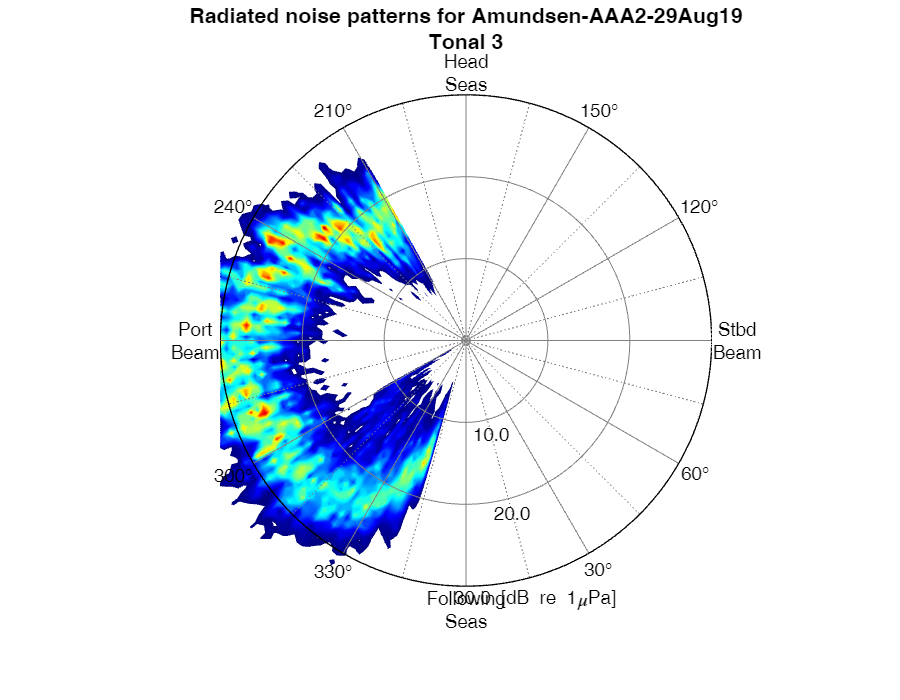

tSL = zeros(length(SPL.rads),par.numRec);    %table of source levels

%get source levels
for iRec = 1:par.numRec
    tSL(:,iRec) = Tonal{iRec,iTonal}(:,1);    %provides 1302x48 table of SLs
end
tSL(tSL<40) = NaN;

%get angles
tw = rad2deg(SPL.rads);  %provides a 1302x48 table of angles
[indw,binw] = discretize(tw,nw); %indw provides the angular index position for each SL

[indSL,binSL] = discretize(tSL,nSL);
%%need to calculate pdf of SLs for each look angle
%pdf or just hist?
pz = zeros(nSL+1,nw+1);    %table of source levels

for iw = 1:nw
    [pz(:,iw),~] = histcounts(tSL(indw == iw),[binSL inf], 'Normalization', 'probability');
end

dirs = binw; %SPL.rads(:,iRec);
SLoffset = binSL-min(binSL); %Tonal{iRec,iTonal}(:,1);
[md,mf] = meshgrid(dirs, SLoffset);
%BDmatrixq = interp2(xrow,ycol,BDmatrix,md,mf,'cubic');
rangeSL = max(max(tSL))-min(min(tSL));
% [md,mf] = meshgrid(rad2deg(SPL.rads(:,iRec)),Tonal{iRec,iTonal}(:,1));

%create the figure
figure(5); clf
ph = makePolarGrid(...
    'ALabelScheme', 'wave2',...
    'RTicks',        0:10:rangeSL,...  % Radial ticks (inner circles)
    'RUnits',        '[dB re 1\muPa]',...   % Add units to outer-most radial labels
    'RLabelFormat', '%.1f');      % Format for radial labels
% 'RTicks',        50:10:rangeSL,...  % Radial ticks (inner circles)
%    'RLim',          [rangeSL-min(min(tSL)) rangeSL],...
% 'RLim',          [rangeSL-min(min(tSL)) rangeSL],...))
 %RTicks --- round(floor(min(min(tSL))),-1):10:ceil(max(max(tSL))),...  % Source Level (dB) ticks (inner circles)

% Now convert to cartesian coords
[px,py] = polgrid2cart(md, mf, ph);

% And then use contourf to plot. Optional formatting adjustments follow.
[~,hc]  = contourf(px, py, pz, 80);
uistack(hc, 'bottom');  % this will put the grid on top of the contours
hc.LevelList(1) = [];    % this removes the countours on lowest level(s)
hc.LineStyle = 'none';  % enable/disble contour lines
colormap jet

caption = sprintf('Radiated noise patterns for %s\nTonal %d',tog.VOI,iTonal);
title(caption, 'FontSize', par.fontSize);

%title({['Radiated noise patterns for ' tog.VOI];['Tonal ' num2str(iTonal)]},'FontSize',par.fontSize)



## Cutting floor

copy of earlier stuff

%
% %want to group these according to tonal source
% for iTonal = 1:par.numTonal
%     subplot(1,par.numTonal,iTonal)
%     polarscatter(SPL.rads(:,iRec),Tonal{iRec,iTonal}(:,1),'.')
%     %rlim(par.nbLim)
%     %thetalim([0 180])
%     rlim([max(Tonal{iRec,iTonal}(:,1))-par.scale max(Tonal{iRec,iTonal}(:,1))])
%     title([num2str(proc.tonals.source(iTonal)) num2str(proc.tonals.harm(iTonal)) ...
%         ' - f = ' num2str(proc.tonals.freq(iTonal)) ' Hz'])
%     if par.numRec == 48
%         hold on
%         for iRec=2:par.scatInt:par.numRec
%             polarscatter(SPL.rads(:,iRec)',Tonal{iRec,iTonal}(:,1),'.')
%         end
%         %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
%     end
%     ax = gca;
%     rruler = ax.RAxis;
%     rruler.Label.String = 'dB re: 1\muPa @ 1m';
%     ax.FontSize = par.fontSize;
%     hold on
%     polarplot(SPL.rads(par.smooth:end,iRec)',smoothdata(Tonal{iRec,iTonal}(par.smooth:end,1),'gaussian',par.smooth),'LineWidth',par.lineWidth)
% end
%
%
% figure(5); clf

Double figure for each tonal showing frequency tracking and source level estimate over time

% h(2) = figure('units','normalized','outerposition',[0 0 1 par.numTonal/3]);
% grid on
%
% %Haven't had luck with this approach
% for iTonal = 1:par.numTonal
%     subplot(par.numTonal,2,2*iTonal-1)
%     hold on
%     for iRec = 1  %:par.numRec
%         hist3([timeVector,Tonal{iRec,iTonal}(:,2)]);%,par.tSize,Tonal{iRec,iTonal}(:,1))
%     end
%     ylabel({'Frequency (Hz)'});
%     xlim([min(timeVector) max(timeVector)]);
%     xline(timeVector(timeCPA),'-.r');
%     ylim([max(Fz(iTonal,:))-par.scale max(Fz(iTonal,:))]);
%     ax = gca; ax.FontSize = 16;
%
%     subplot(par.numTonal,2,2*iTonal)
%     hold on
%     for iRec = 1:par.numRec
%         scatter(timeVector,Tonal{iRec,iTonal}(:,1),par.tSize,Tonal{iRec,iTonal}(:,1))
%     end
%     ylabel({'SPL (dB re 1\muPa)'});
%     xlim([min(timeVector) max(timeVector)]);
%     xline(timeVector(timeCPA),'-.r');
%     ylim([max(Tonal{iRec,iTonal}(:,1))-par.spread max(Tonal{iRec,iTonal}(:,1))]);
%     ax = gca; ax.FontSize = 16;
% end
%

Polar plot of tonal lobing patterns

% %2021/07/12 working on this section
% %want to group these according to tonal source
%
%
% h(3) = figure('units','normalized','outerposition',[0 0 par.numTonal/4 0.75]);
% sgtitle('Radiated noise patterns')
%
%
% for iTonal = 1; :par.numTonal
%     iRec = 1;
%     %subplot(1,par.numTonal,iTonal)
%
%     x = rad2deg(double(SPL.rads(:,iRec)));
%     y = Tonal{iRec,iTonal}(:,2); %Tonal{iRec,iTonal}(:,1)
%     N = hist3([x,y],'Nbins',[50 50]);
%     N_pcolor = N';
%     N_pcolor(size(N_pcolor,1)+1,size(N_pcolor,2)+1) = 0;
%     xl = linspace(min(x),max(x),size(N_pcolor,2)); % Columns of N_pcolor
%     yl = linspace(min(y),max(y),size(N_pcolor,1)); % Rows of N_pcolor
%
%     h = pcolor(xl,yl,N_pcolor);
%     colormap('hot') % Change color scheme
%     colorbar % Display colorbar
%     h.ZData = -max(N_pcolor(:))*ones(size(N_pcolor));
%     ax = gca;
%     ax.ZTick(ax.ZTick < 0) = [];
%     title('Source level aspect probability density');
%     ylabel({'SPL (dB re 1\muPa)'});
%     ylabel({'Frequency (Hz)'});
%     xlabel('Aspect (\deg)')
%
%
%     heatscatter(x,y,fullfile(par.figPath,tog.VOI),'heatScat.tif');
%
%
%     %rlim(par.nbLim)
%     %thetalim([0 180])
%     rlim([max(Tonal{iRec,iTonal}(:,1))-par.scale max(Tonal{iRec,iTonal}(:,1))])
%     title([num2str(proc.tonals.source(iTonal)) num2str(proc.tonals.harm(iTonal)) ...
%         ' - f = ' num2str(proc.tonals.freq(iTonal)) ' Hz'])
%     if par.numRec == 48
%         hold on
%         for iRec=2:par.scatInt:par.numRec
%             polarscatter(SPL.rads(:,iRec)',Tonal{iRec,iTonal}(:,1),'.')
%         end
%         %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
%     end
%     ax = gca;
%     rruler = ax.RAxis;
%     rruler.Label.String = 'dB re: 1\muPa @ 1m';
%     ax.FontSize = par.fontSize;
%     hold on
%     polarplot(SPL.rads(par.smooth:end,iRec)',smoothdata(Tonal{iRec,iTonal}(par.smooth:end,1),'gaussian',par.smooth),'LineWidth',par.lineWidth)
% end
%
% if tog.saveFigs
%     saveas(h(1), fullfile(par.figPath,tog.VOI,'fTracking.tif'));
%     saveas(h(2), fullfile(par.figPath,tog.VOI,'fTracking6.tif'));
%     saveas(h(3), fullfile(par.figPath,tog.VOI,'rnlPattern.tif'));
%     savefig(h,fullfile(par.figPath,tog.VOI,'NBLobing'));
% end
%
% end

